%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Car: Mk.11
% Subteam: Vehicle Dynamics  
% Description: Ackermann Percentage Analysis
% Use Case: Given tire loads and tire line of peaks, find desired Ackermann
% percentage through balancing scrub and slip penalties.
% Current Edit Date: 08/05/2025
% Last Edited By: Tahbert Bui
% Author(s): Tahbert Bui
% References: VD11_001_Wheel_Forces
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 

clc; close all; clear; addpath("Functions")


## Vehicle Parameters

res = 1000;

wheelbase = 61; % in
trackwidth = 45; % in
W = 671; % weight of car + avg driver weight (total weight, lbs)
W_us = 83.87; %unsprung mass 
W_s = W-W_us; %sprung mass
CG_z = 11.1; % height of CoG in z-axis (vertical) in
CG_x = 34.465; %x position of CG from front axle
a = CG_x;
b = wheelbase - CG_x;

Z_RF = 1.5; % in Front Roll Center Height
Z_RR = 2; % in Rear Roll Center Height

Cd = 1.41;
Cl = 3.42;
Area = 12.3139; %frontal area ft^2
CoP_x_bias = 0.47; %center of pressure front/rear bias              
CoP_z = 27; % center of pressure height from ground (z-axis) in
rho = 0.002134; % , air density slug/ft3
v = 51.3; %velocity in ft/s from CFD sim 
        %Important note: this assumes constant velocity 
        %across the g-g diagram.    

%Ride and Roll Rates
Kphi_F_max = 12000; %ft*lbf/rad 
Kphi_R_max = 13000; %ft*lbf/rad
Kr_F = 118.3094; %lbf/in
Kr_R = 119.6025; %lbf/in
Ks = 225; %lbf/in
MR_F = 1.177; %wheel to shock travel
MR_R = 1.168; %wheel to shock travel
shock_travel = 1.85; %inches
brake_bias = 0.60;


## Ackermann: set up line of peaks

% tir file setup
% R20 is Mk10 tire, likely to be Mk11 selected tire
root = "C:\Users\user\Desktop\uni tudd\bfrSoft\TT"

root = "C:\Users\user\Desktop\uni tudd\bfrSoft\TT"

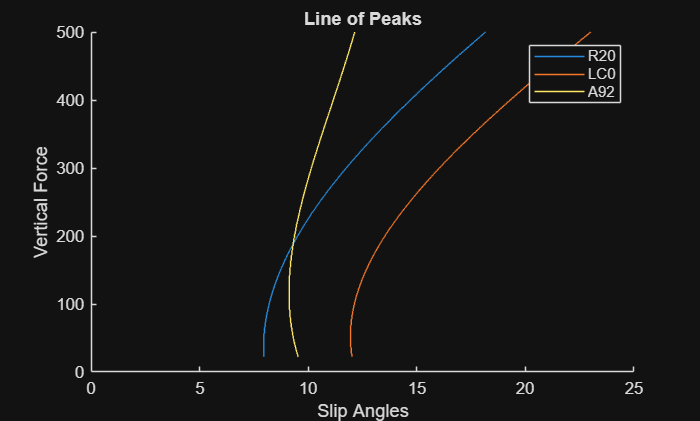

TIRfilepath = mfeval.readTIR("C:\Users\user\Desktop\uni tudd\bfrSoft\TT\tirFiles\magicformula_R20.tir");
TIRfilepath2 = mfeval.readTIR("C:\Users\user\Desktop\uni tudd\bfrSoft\TT\tirFiles\magicformula_LC0.tir");
TIRfilepath3 = mfeval.readTIR("C:\Users\user\Desktop\uni tudd\bfrSoft\TT\tirFiles\magicformula_A92.tir");
lbToN = 4.44822;

kappa = zeros(res, 1); % assuming zero long slip ratio; valid for SS lat accel
alpha = linspace(0, deg2rad(30), res)'; % slip angle
gamma = zeros(res, 1); % assuming 0 deg camber
phit = zeros(res, 1); % zero banking angle
P = ones(res,1).*82737.1; % 12 psi in Pa
Vx = ones(res, 1).* 10; % assuming 10 m/s for now
Fz = linspace(100, 500*lbToN, res)'; % 0-500 lbf, arbitrarily
useMode = 111; % don't change

maxSlips = zeros(res, 1);
maxSlips2 = zeros(res, 1);
maxSlips3 = zeros(res, 1);

for i = 1:length(Fz)
    Fz_iter = ones(res, 1) .* Fz(i, 1);
    tirInputs = [Fz_iter kappa alpha gamma phit Vx P]; 
    tirOutputs = mfeval(TIRfilepath, tirInputs, useMode);
    tirOutputs2 = mfeval(TIRfilepath2, tirInputs, useMode);
    tirOutputs3 = mfeval(TIRfilepath3, tirInputs, useMode);
    Fy_iter = tirOutputs(:, 2) ./ lbToN .* -1;
    Fy_iter2 = tirOutputs2(:, 2) ./ lbToN .* -1;
    Fy_iter3 = tirOutputs3(:, 2) ./ lbToN .* -1;
    SA = rad2deg(tirOutputs(:, 8));
    SA2 = rad2deg(tirOutputs2(:, 8));
    SA3 = rad2deg(tirOutputs3(:, 8));
    maxSlips(i) = findOptimalSA(SA, Fy_iter);
    maxSlips2(i) = findOptimalSA(SA2, Fy_iter2);
    maxSlips3(i) = findOptimalSA(SA3, Fy_iter3);
end

Fz_out = Fz / lbToN;
maxSlips = [maxSlips, Fz_out(:), Fy_iter(:)]; 
maxSlips2 = [maxSlips2, Fz_out(:)]; 
maxSlips3 = [maxSlips3, Fz_out(:)];

save R20peakline.mat maxSlips;

% plot line of peaks
figure(13)
clf;
ylabel("Vertical Force")
xlabel("Slip Angles")
title("Line of Peaks")
hold on 
plot(maxSlips(:, 1), maxSlips(:, 2))
plot(maxSlips2(:, 1), maxSlips2(:, 2))
plot(maxSlips3(:, 1), maxSlips3(:, 2))
legend("R20", "LC0", "A92")
xlim([0 25]);
hold off

## Ackermann analysis plots

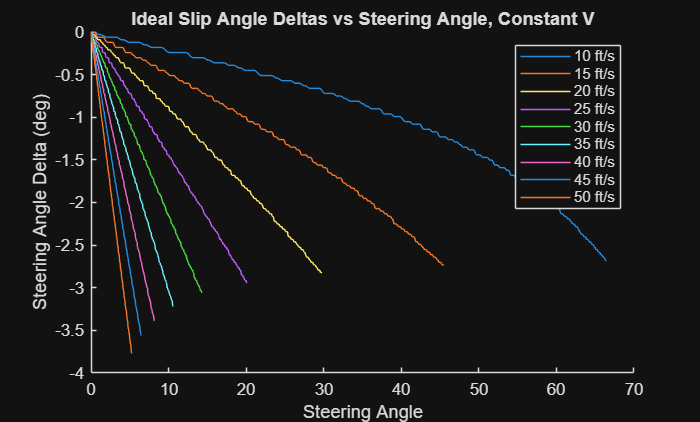

% calculate ideal slip angle difference in cornering given
% inner and outer tire vertical loads and the line of peaks
% calculated above

% correlate corner radius to turning angle
% turning angle = arctan(wheelbase / corner radius)
% and corner radius = tan(turning angle) / wheelbase
% instead of corner radius, could be just car turn radius

% correlate turning angle to Ackermann
% perfect Ackermann diff: inner and outer tire have same turn center
% so inner tire angle = arctan(wheelbase / (corner radius - 1/2 * trackwidth))
% and outer tire angle = arctan(wheelbase / (corner radius + 1/2 * trackwidth))
% therefore ackermann delta = inner - outer, 
% and ackermann percentage is defined as actual delta / ideal delta,
% so any delta given ackermann percent is percent * ideal delta
% and I can graph this now!

% test case -- 40% anti to 100% pro Ackermann, 20% intervals, visualized
ackPercent = linspace(100, -40, 8)';
steeredAngle = linspace(0, 30, res)';
wheelbaseIter = ones(res, 1) .* wheelbase;
trackwidthIter = ones(res, 1) .* trackwidth;

% ideal slip angle to steering angle 
% constant v, sweep through a
latAccelSweep = linspace(0, 1.4, res)';
vTestRange = [10; 15; 20; 25; 30; 35; 40; 45; 50];
latSlipDeltas = zeros(res, length(vTestRange));
steerOuts = zeros(res, length(vTestRange));

for i = 1:length(vTestRange)
    derivedCornerRadius = vTestRange(i).^2 ./ (latAccelSweep .* 32.17405);
    steerAngleIdeal = atand((wheelbaseIter ./ 12) ./ derivedCornerRadius);
    latDeltas = zeros(res, 1);

    paramsTestV = struct( ...
        'wheelbase', wheelbase, 'trackwidth', trackwidth, 'W', W, ...
        'CG_x', CG_x, 'CG_z', CG_z, 'Z_RF', Z_RF, 'Z_RR', Z_RR, ...
        'Kphi_F', Kphi_F_max, 'Kphi_R', Kphi_R_max, 'brake_bias', brake_bias, ...
        'Cd', Cd, 'Cl', Cl, 'area', Area, ...
        'CoP_bias', CoP_x_bias, 'CoP_z', CoP_z, ...
        'rho', rho, 'velocity', vTestRange(i) ...
    );

    for j = 1:res
        latAccelPoint = [latAccelSweep(j), 0];
        [FL_choose, FR_choose, ~, ~, ~] = calculateLoadTransfer(paramsTestV, latAccelPoint);
        [~, ~, latDeltas(j)] = findSlipDelta(FR_choose(3), FL_choose(3), maxSlips(:, 1), maxSlips(:, 2));
    end
    latSlipDeltas(:, i) = latDeltas;
    steerOuts (:, i) = steerAngleIdeal;
end

% constant a, sweep through v
vSweep = linspace(1, 60, res)';
latTestRange = [0.6; 0.7; 0.8; 0.9; 1.0; 1.1; 1.2; 1.3;];
latSlipDeltasA = zeros(res, length(latTestRange));
steerOutsA = zeros(res, length(latTestRange));

for i = 1:length(latTestRange)
    derivedCornerRadiusA = vSweep.^2 ./ (latTestRange(i) .* 32.17405);
    steerAngleIdealA = atand((wheelbaseIter ./ 12) ./ derivedCornerRadiusA);
    latDeltasA = zeros(res, 1);
    for j = 1:res
        paramsTestA = struct( ...
            'wheelbase', wheelbase, 'trackwidth', trackwidth, 'W', W, ...
            'CG_x', CG_x, 'CG_z', CG_z, 'Z_RF', Z_RF, 'Z_RR', Z_RR, ...
            'Kphi_F', Kphi_F_max, 'Kphi_R', Kphi_R_max, 'brake_bias', brake_bias, ...
            'Cd', Cd, 'Cl', Cl, 'area', Area, ...
            'CoP_bias', CoP_x_bias, 'CoP_z', CoP_z, ...
            'rho', rho, 'velocity', vSweep(j) ...
        );
        latAccelPointA = [latTestRange(i), 0];
        [FL_choose, FR_choose, ~, ~, ~] = calculateLoadTransfer(paramsTestA, latAccelPointA);
        [~, ~, latDeltasA(j)] = findSlipDelta(FR_choose(3), FL_choose(3), maxSlips(:, 1), maxSlips(:, 2));
    end
    latSlipDeltasA(:, i) = latDeltasA;
    steerOutsA(:, i) = steerAngleIdealA;
end

% assumption that lat accel scales linearly with corner radius and derive
% velocity from there, best i can do for now probably
cornerToAccel = [5; 10; 15; 20; 25; 30; 35; 40; 45; 50; 55; 60; 65; 70;];
accelToCorner = [0.6; 0.7; 0.8; 0.9; 1.0; 1.1; 1.2; 1.3; 1.4; 1.5; 1.6; 1.7; 1.8; 1.9;];
newSlipDeltas = zeros(res, 1);
newSteerOuts = zeros(res, 1);
newLatAccelSweep = linspace(0.6, 1.8, res)'; 
for i = 1:res
    corner = interp1(accelToCorner, cornerToAccel, newLatAccelSweep(i));
    cornerV = sqrt(newLatAccelSweep(i) * corner);
    steer = atand((wheelbase ./ 12) ./ corner);
    newParams = struct( ...
        'wheelbase', wheelbase, 'trackwidth', trackwidth, 'W', W, ...
        'CG_x', CG_x, 'CG_z', CG_z, 'Z_RF', Z_RF, 'Z_RR', Z_RR, ...
        'Kphi_F', Kphi_F_max, 'Kphi_R', Kphi_R_max, 'brake_bias', brake_bias, ...
        'Cd', Cd, 'Cl', Cl, 'area', Area, ...
        'CoP_bias', CoP_x_bias, 'CoP_z', CoP_z, ...
        'rho', rho, 'velocity', cornerV ...
    );
    newAccelPoint = [newLatAccelSweep(i), 0];
    [FL_new, FR_new, ~, ~, ~] = calculateLoadTransfer(newParams, newAccelPoint);
    newSteerOuts(i) = steer;
    [~, ~, newSlipDeltas(i)] = findSlipDelta(FR_new(3), FL_new(3), maxSlips(:, 1), maxSlips(:, 2));
end


figure(1)
clf;
ylabel("Steering Angle Delta (deg)")
xlabel("Steering Angle")
title("Ideal Slip Angle Deltas vs Steering Angle, Constant V")
hold on
for i = 1:length(vTestRange)
    plot(steerOuts(:, i), latSlipDeltas(:, i))
end

legend("10 ft/s", "15 ft/s", "20 ft/s", "25 ft/s", "30 ft/s", "35 ft/s", ...
       "40 ft/s", "45 ft/s", "50 ft/s")
hold off

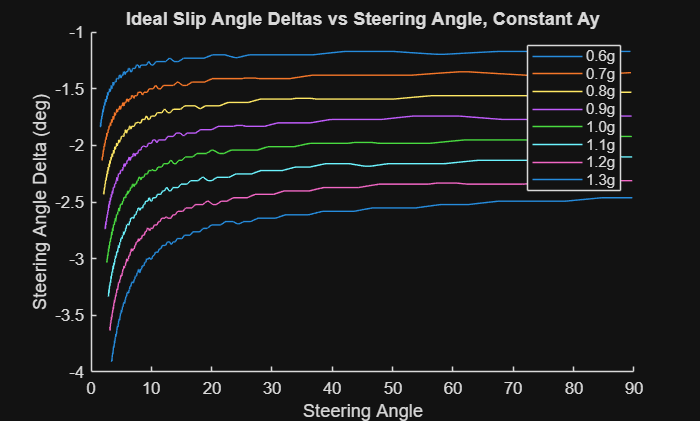


figure(2)
clf;
ylabel("Steering Angle Delta (deg)")
xlabel("Steering Angle")
title("Ideal Slip Angle Deltas vs Steering Angle, Constant Ay")
hold on
for i = 1:length(latTestRange)
    plot(steerOutsA(:, i), latSlipDeltasA(:, i))
end

legend("0.6g", "0.7g", "0.8g", "0.9g", "1.0g", "1.1g", ...
       "1.2g", "1.3g")
hold off

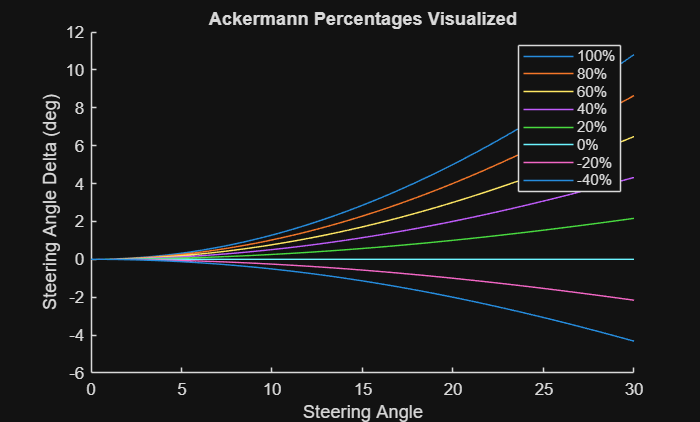


figure(3)
clf;
ylabel("Steering Angle Delta (deg)")
xlabel("Steering Angle")
title("Ackermann Percentages Visualized")
hold on
for i = 1:length(ackPercent)
    ackPercentIter = ones(res, 1) .* ackPercent(i);
    ackDeltas = ackPlot(wheelbaseIter, trackwidthIter, steeredAngle, ackPercentIter);
    plot(steeredAngle, ackDeltas)
end
legend("100%", "80%", "60%", "40%", "20%", "0%", "-20%", "-40%")
hold off

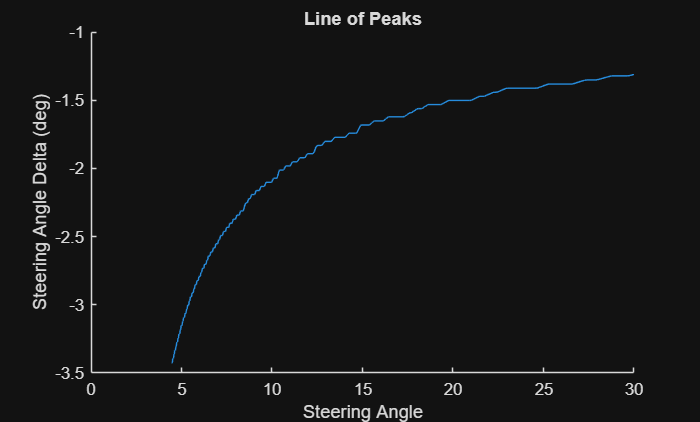


figure(4)
clf;
ylabel("Steering Angle Delta (deg)")
xlabel("Steering Angle")
title("Line of Peaks")
hold on
plot(newSteerOuts, newSlipDeltas)
xlim([0 30]);
hold off

## Ackermann tradeoff analysis

% sweepRes = 300;
% ackSweep = linspace(16.2, 16.5, sweepRes)'; 
ackSweep = [-18.8020, 16.3294];
sweepRes = length(ackSweep);
ackAvgPenalties = zeros(sweepRes, 1);
ackAvgSlip = zeros(sweepRes, 1);
ackAvgScrub = zeros(sweepRes, 1);
scrubPens = zeros(res, sweepRes);
slipPens = zeros(res, sweepRes);
prop = zeros(res, 1);
scrubScale = 70000; % 2000 for wide corners, 70000 for tight corners

ackPerfAdjusted = ackPlot(wheelbaseIter, trackwidthIter, newSteerOuts, 100);

for i = 1:sweepRes
    scrubPenInt = zeros(res, 1);
    slipPenInt = zeros(res, 1);
    propInt = zeros(res, 1);
    ackLoop = ackPlot(wheelbaseIter, trackwidthIter, newSteerOuts, ackSweep(i));
    for j = 1:res
        ackDiff = ackPerfAdjusted(j) - ackLoop(j);
        idealDiff = abs(ackLoop(j) - newSlipDeltas(j));
        latAccelCase = newLatAccelSweep(j);
        pointCase = [latAccelCase, 0];
        steerCase = newSteerOuts(j);
        cornerCase = (wheelbase / 12) / tand(steerCase);
        vCase = sqrt(latAccelCase * cornerCase);
        paramsCase = struct( ...
        'wheelbase', wheelbase, 'trackwidth', trackwidth, 'W', W, ...
        'CG_x', CG_x, 'CG_z', CG_z, 'Z_RF', Z_RF, 'Z_RR', Z_RR, ...
        'Kphi_F', Kphi_F_max, 'Kphi_R', Kphi_R_max, 'brake_bias', brake_bias, ...
        'Cd', Cd, 'Cl', Cl, 'area', Area, ...
        'CoP_bias', CoP_x_bias, 'CoP_z', CoP_z, ...
        'rho', rho, 'velocity', vCase);
        [FL_input, FR_input, ~, ~, ~] = calculateLoadTransfer(paramsCase, pointCase);
        [innerIdeal, outerIdeal, ~] = findSlipDelta(FR_input(3), FL_input(3), maxSlips(:, 1), maxSlips(:, 2));
        proportion = FL_input(3) ./ (FL_input(3) + FR_input(3));
        % slip penalty
        CS_outer = FL_input(2) / outerIdeal;
        CS_inner = FR_input(2) / innerIdeal;
        innerActual = innerIdeal + proportion * idealDiff;
        outerActual = outerIdeal - (1 - proportion) * idealDiff;
        % ideally this would go off of tire data, but mfeval really really
        % does not like low Fz loads, so cornering stiffness is used
        FyInnerSlip = CS_inner * abs(innerActual - innerIdeal);
        FyOuterSlip = CS_outer * abs(outerActual - outerIdeal);
        slipPenInt(j) = FyInnerSlip + FyOuterSlip;

        % scrub penalty
        innerAckDiff = proportion * ackDiff;
        outerAckDiff = (1 - proportion)* ackDiff;
        % geometric vector penalty
        FyInnerScrub = abs(FR_input(1)) - abs(FR_input(1) * cosd(innerAckDiff));
        FyOuterScrub = abs(FL_input(1)) - abs(FL_input(1) * cosd(outerAckDiff));
        scrubPenInt(j) = FyInnerScrub + FyOuterScrub;
        prop(j) = proportion;

    end
    penalty = scrubScale .* scrubPenInt + slipPenInt;
    ackAvgPenalties(i) = mean(penalty);
    ackAvgScrub(i) = mean(scrubPenInt);
    ackAvgSlip(i) = mean(slipPenInt);
    scrubPens(:, i) = scrubPenInt;
    slipPens(:, i) = slipPenInt;
end

[minPenalty, indexMinPenalty] = min(ackAvgPenalties);
targetAck = ackSweep(indexMinPenalty);
fprintf("Best Ackermann Percentage: %.4f\n", targetAck);

Best Ackermann Percentage: 16.3294


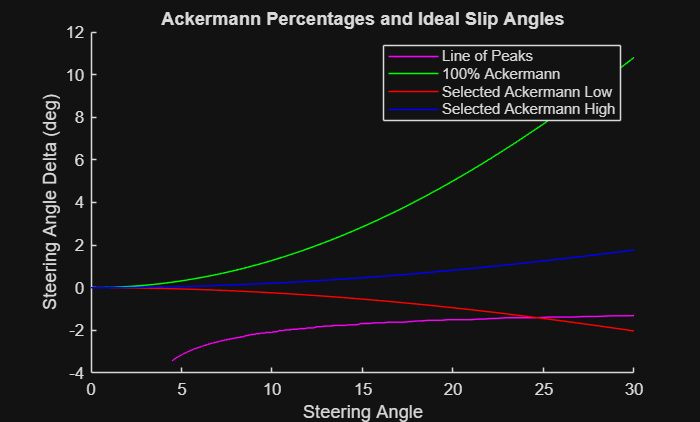


figure(5)
clf;
ylabel("Steering Angle Delta (deg)")
xlabel("Steering Angle")
title("Ackermann Percentages and Ideal Slip Angles")
hold on
% for i = 1:length(ackPercent)
%     ackPercentIter = ones(res, 1) .* ackPercent(i);
%     ackDeltas = ackPlot(wheelbaseIter, trackwidthIter, steeredAngle, ackPercentIter);
%     plot(steeredAngle, ackDeltas, 'color', 'red')
% end
% for i = 1:length(vTestRange)
%     plot(steerOuts(:, i), latSlipDeltas(:, i), 'color', 'blue')
% end
% for i = 1:length(latTestRange)
%     plot(steerOutsA(:, i), latSlipDeltasA(:, i), 'color', 'magenta')
% end
plot(newSteerOuts, newSlipDeltas, 'color', 'magenta') 
ackPerfDeltas = ackPlot(wheelbaseIter, trackwidthIter, steeredAngle, 100);
plot(steeredAngle, ackPerfDeltas, 'color', 'green')
ackChosenDeltasLow = ackPlot(wheelbaseIter, trackwidthIter, steeredAngle, -18.8020);
plot(steeredAngle, ackChosenDeltasLow, 'color', 'red')
ackChosenDeltasHigh = ackPlot(wheelbaseIter, trackwidthIter, steeredAngle, 16.3294);
plot(steeredAngle, ackChosenDeltasHigh, 'color', 'blue')
xlim([0 30])
legend("Line of Peaks", "100% Ackermann", "Selected Ackermann Low", "Selected Ackermann High")
hold off



% low avg slip pen: 20.4031
% parallel avg slip pen: 23.2957
% 6.0142% avg slip pen: 25
% high avg slip pen: 27.9232
% 23.6578% avg slip pen: 30
% 100% avg slip pen: 51.6343

% good news: slip angles are dependent on Fz, which we know given accel
% cases. bad news: accel cases don't neatly line up with corner radii. good
% news: we know skidpad lateral accel case and skidpad radius, so if we
% assume ss pure cornering, we know velocity, which can be used to relate
% corner radii and lat accel. for now (a = v^2 / r), velocity is assumed 
% to be same as that from skidpad case. now slip angles can be properly
% correlated with steering angles!

% endgoal: correlate slip angles to corner radii
% to get there: correlate lat accel to corner radii, find fz values for
% lat accel values, correlate fz values to corner radii, find slip angles 
% for fz values, find delta


## test code

% % sweepRes = 300;
% % ackSweep = linspace(16.2, 16.5, sweepRes)'; 
% ackSweep = [-18.8020, 16.3294];
% sweepRes = length(ackSweep);
% ackAvgPenalties = zeros(sweepRes, 1);
% ackAvgSlip = zeros(sweepRes, 1);
% ackAvgScrub = zeros(sweepRes, 1);
% scrubPens = zeros(res, sweepRes);
% slipPens = zeros(res, sweepRes);
% prop = zeros(res, 1);
% scrubScale = 70000; % 2000 for wide corners, 70000 for tight corners
% Fz_min = 30 * lbToN; % clamps for Fz and alpha
% alpha_max = 12;
% 
% ackPerfAdjusted = ackPlot(wheelbaseIter, trackwidthIter, newSteerOuts, 100);
% for i = 1:sweepRes
%     scrubPenInt = zeros(res, 1);
%     slipPenInt = zeros(res, 1);
%     propInt = zeros(res, 1);
%     ackLoop = ackPlot(wheelbaseIter, trackwidthIter, newSteerOuts, ackSweep(i));
%     for j = 1:res
%         ackDiff = ackPerfAdjusted(j) - ackLoop(j);
%         idealDiff = abs(ackLoop(j) - newSlipDeltas(j));
%         latAccelCase = newLatAccelSweep(j);
%         pointCase = [latAccelCase, 0];
%         steerCase = newSteerOuts(j);
%         cornerCase = (wheelbase / 12) / tand(steerCase);
%         vCase = sqrt(latAccelCase * cornerCase);
%         paramsCase = struct( ...
%         'wheelbase', wheelbase, 'trackwidth', trackwidth, 'W', W, ...
%         'CG_x', CG_x, 'CG_z', CG_z, 'Z_RF', Z_RF, 'Z_RR', Z_RR, ...
%         'Kphi_F', Kphi_F_max, 'Kphi_R', Kphi_R_max, 'brake_bias', brake_bias, ...
%         'Cd', Cd, 'Cl', Cl, 'area', Area, ...
%         'CoP_bias', CoP_x_bias, 'CoP_z', CoP_z, ...
%         'rho', rho, 'velocity', vCase);
%         [FL_input, FR_input, ~, ~, ~] = calculateLoadTransfer(paramsCase, pointCase);
%         [innerIdeal, outerIdeal, ~] = findSlipDelta(FR_input(3), FL_input(3), maxSlips(:, 1), maxSlips(:, 2));
%         proportion = FL_input(3) ./ (FL_input(3) + FR_input(3));
%         % slip penalty
%         CS_outer = FL_input(2) / outerIdeal;
%         CS_inner = FR_input(2) / innerIdeal;
%         innerActual = innerIdeal + proportion * idealDiff;
%         outerActual = outerIdeal - (1 - proportion) * idealDiff;
%         if FR_input(3) >= Fz_min && innerActual <= alpha_max
%             alpha = deg2rad(innerActual);
%             Fz_innerActual = FR_input(3) * lbToN;
%             v = max(vCase, 2);
%             tirInputIter = [Fz_innerActual 0 alpha 0 0 v 82737.1];
%             tirOutputIter = mfeval(TIRfilepath, tirInputIter, useMode);
%             Fy_innerActual = abs(tirOutputIter(:, 2) ./ lbToN);
%             FyInnerSlip = abs(FR_input(2) - Fy_innerActual);
%         else
%             FyInnerSlip = CS_inner * abs(innerActual - innerIdeal);
%         end
%         if FL_input(3) >= Fz_min && outerActual <= alpha_max
%             alpha = deg2rad(outerActual);
%             Fz_outerActual = FL_input(3) * lbToN;
%             v = max(vCase, 2);
%             tirInputIter = [Fz_outerActual 0 alpha 0 0 v 82737.1];
%             tirOutputIter = mfeval(TIRfilepath, tirInputIter, useMode);
%             Fy_outerActual = abs(tirOutputIter(:, 2) ./ lbToN);
%             FyOuterSlip = abs(FL_input(2) - Fy_outerActual);
%         else
%             FyOuterSlip = CS_outer * abs(outerActual - outerIdeal);
%         end
%         slipPenInt(j) = FyInnerSlip + FyOuterSlip;
% 
%         % scrub penalty
%         innerAckDiff = proportion * ackDiff;
%         outerAckDiff = (1 - proportion)* ackDiff;
%         % geometric vector penalty
%         FyInnerScrub = abs(FR_input(1)) - abs(FR_input(1) * cosd(innerAckDiff));
%         FyOuterScrub = abs(FL_input(1)) - abs(FL_input(1) * cosd(outerAckDiff));
%         scrubPenInt(j) = FyInnerScrub + FyOuterScrub;
%         prop(j) = proportion;
% 
%     end
%     penalty = scrubScale .* scrubPenInt + slipPenInt;
%     ackAvgPenalties(i) = mean(penalty);
%     ackAvgScrub(i) = mean(scrubPenInt);
%     ackAvgSlip(i) = mean(slipPenInt);
%     scrubPens(:, i) = scrubPenInt;
%     slipPens(:, i) = slipPenInt;
% end

% for i = 1:sweepRes
%     scrubPenInt = zeros(res, 1);
%     slipPenInt = zeros(res, 1);
%     propInt = zeros(res, 1);
%     ackLoop = ackPlot(wheelbaseIter, trackwidthIter, newSteerOuts, ackSweep(i));
%     for j = 1:res
%         ackDiff = ackPerfAdjusted(j) - ackLoop(j);
%         idealDiff = abs(ackLoop(j) - newSlipDeltas(j));
%         latAccelCase = newLatAccelSweep(j);
%         pointCase = [latAccelCase, 0];
%         steerCase = newSteerOuts(j);
%         cornerCase = (wheelbase / 12) / tand(steerCase);
%         vCase = sqrt(latAccelCase * cornerCase);
%         paramsCase = struct( ...
%         'wheelbase', wheelbase, 'trackwidth', trackwidth, 'W', W, ...
%         'CG_x', CG_x, 'CG_z', CG_z, 'Z_RF', Z_RF, 'Z_RR', Z_RR, ...
%         'Kphi_F', Kphi_F_max, 'Kphi_R', Kphi_R_max, 'brake_bias', brake_bias, ...
%         'Cd', Cd, 'Cl', Cl, 'area', Area, ...
%         'CoP_bias', CoP_x_bias, 'CoP_z', CoP_z, ...
%         'rho', rho, 'velocity', vCase);
%         [FL_input, FR_input, ~, ~, ~] = calculateLoadTransfer(paramsCase, pointCase);
%         [innerIdeal, outerIdeal, ~] = findSlipDelta(FR_input(3), FL_input(3), maxSlips(:, 1), maxSlips(:, 2));
%         proportion = FL_input(3) ./ (FL_input(3) + FR_input(3));
%         % slip penalty
%         CS_outer = FL_input(2) / outerIdeal;
%         CS_inner = FR_input(2) / innerIdeal;
%         innerActual = innerIdeal + proportion * idealDiff;
%         outerActual = outerIdeal - (1 - proportion) * idealDiff;
%         % ideally this would go off of tire data, but mfeval really really
%         % does not like low Fz loads, so cornering stiffness is used
%         FyInnerSlip = CS_inner * abs(innerActual - innerIdeal);
%         FyOuterSlip = CS_outer * abs(outerActual - outerIdeal);
%         slipPenInt(j) = FyInnerSlip + FyOuterSlip;
% 
%         % scrub penalty
%         innerAckDiff = proportion * ackDiff;
%         outerAckDiff = (1 - proportion)* ackDiff;
%         % geometric vector penalty
%         FyInnerScrub = abs(FR_input(1)) - abs(FR_input(1) * cosd(innerAckDiff));
%         FyOuterScrub = abs(FL_input(1)) - abs(FL_input(1) * cosd(outerAckDiff));
%         scrubPenInt(j) = FyInnerScrub + FyOuterScrub;
%         prop(j) = proportion;
% 
%     end
%     penalty = scrubScale .* scrubPenInt + slipPenInt;
%     ackAvgPenalties(i) = mean(penalty);
%     ackAvgScrub(i) = mean(scrubPenInt);
%     ackAvgSlip(i) = mean(slipPenInt);
%     scrubPens(:, i) = scrubPenInt;
%     slipPens(:, i) = slipPenInt;
% end
